# Test/ Debugger: imgCropMULTI 

**Summary: **Works through step by step the preprocessing and cropping stages. Useful for code debugging and investigating preprocessing quality of a particular frame.

**User notes:**

1) Make sure videos and individual video frames that wished to be investigated are located in the same folder as this live script.

2) Ammend necessary inputs, particularly video/ image file name. Other hyperparameters can also be adjusted as see fit.

V1.1. SWC, 10 Feb 2021.

## 1) Load video

% vid_file_name = 'SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'; %<-------- user-defined input!!
vid_file_name = '52%Gl_W_0.003_Ink_SO_SPAN80_0.003_2kfps_.avi';
vid = VideoReader(vid_file_name); %read video 
totframes = vid.NumFrames %check total num of frames in video

totframes = 5741

## 2a) Background generation - 'Basic'

Shows 3 methods: i) Mean, ii) Median and iii) Mode

n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
mean_pix = mean(frameMat,3,'native'); %compute mean of each pixel across all frames in matrix
toc

Elapsed time is 2.902556 seconds.



tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 0.243789 seconds.


tic
max_pix = mode(frameMat,3); %compute mode of each pixel across all frames in matrix
toc

Elapsed time is 1.361390 seconds.


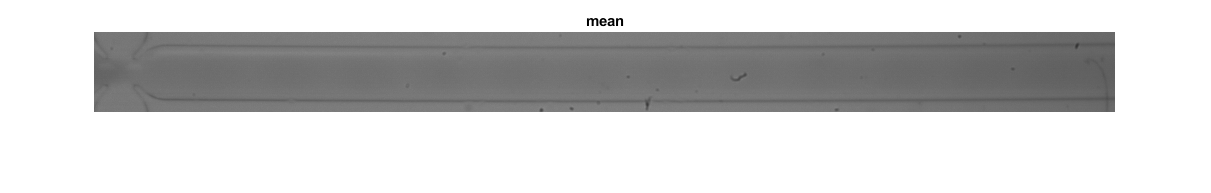

%show generated background 
figure; imshow(mean_pix); title('mean'); % to use imshow with 'double' class type, need to rescale to range [0 1]

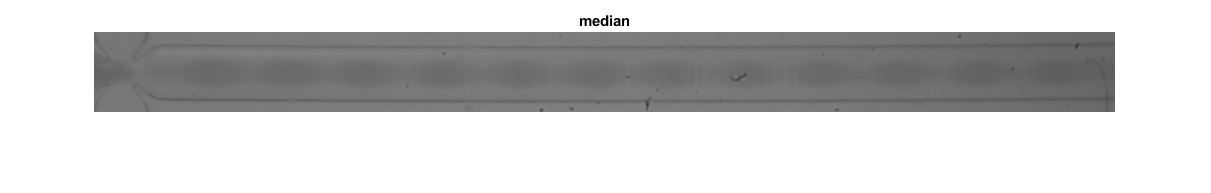

figure; imshow(med_pix); title('median')

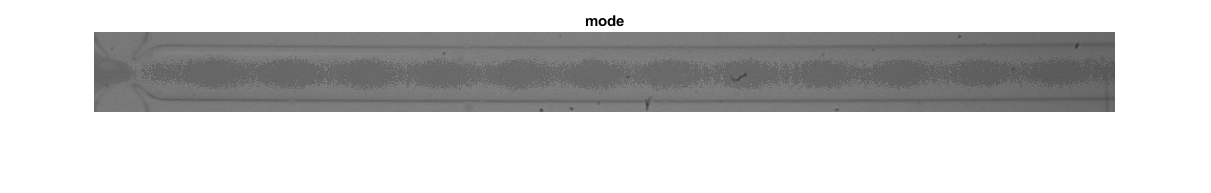


figure; imshow(max_pix); title('mode')

## 2b) Background generation - 'Complex' 

### (Adapted from ADM method)

n = 40;    % number of frames to use for background generation

idx = randperm(totframes,n); %vector of index of frame number to be extracted; randomly selected
frameMat = [];

% for loop to create matrix of frames - for generating background image
for j=1:numel(idx)
    frame = read(vid,idx(j));
    frameMat = cat(3,frameMat,frame);
end

bg = mean(frameMat,3,'native'); %compute mean value of each pixel across all frames in matrix

Imin = double(min(bg,[],'all'))

Imin = 53

Imax = double(max(bg,[],'all'))

Imax = 134

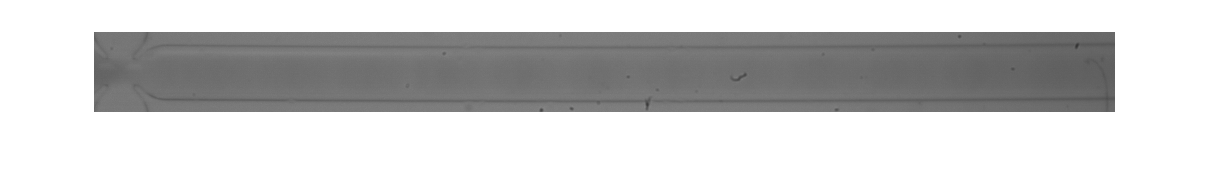


figure; imshow(bg)

tic;
f = randperm(totframes,n);

Al2 = (245*(double(bg)-Imin))/(Imax-Imin) + 10;
R = bg;

for nf = 1:length(f)
    F = read(vid, f(nf));
    Fl2 = (245*(double(F)-Imin))/(Imax-Imin) + 10;
    
    D = 255.* Fl2 ./ Al2;
    D(Al2 <= 0 | Fl2 > Al2) = 255;
    D(Fl2 < 0) = 0;
%     D = mat2gray(D);
    D = rescale(D);
    
    B1 = imbinarize(D);
    B2 = imcomplement(B1);
    
    B2_fill = bwconvhull(B2,'object');
    B2_fill = bwareaopen(B2_fill,1000);
    A2 = regionprops('table',B2_fill,'BoundingBox');
    se = strel('disk', round(0.3*min(A2.BoundingBox(:,3))));
    B2_dilate = imdilate(B2_fill,se);
    M2 = uint8(double(R).*double(B2_dilate));
    
    B1_dilate = imcomplement(B2_dilate);
    M1 = uint8(double(B1_dilate).*double(F));
    
    R = M1+M2;
    
    %     figure; imshow(M1); figure; imshow(M2);
    %     figure; imshow(R);
    
end
toc;

Elapsed time is 7.436814 seconds.


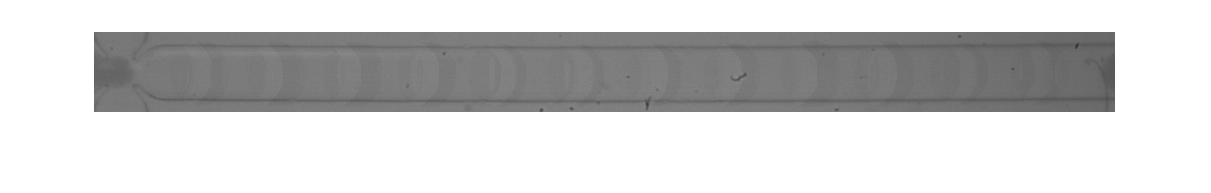


figure; imshow(R)

## 3) Load image 

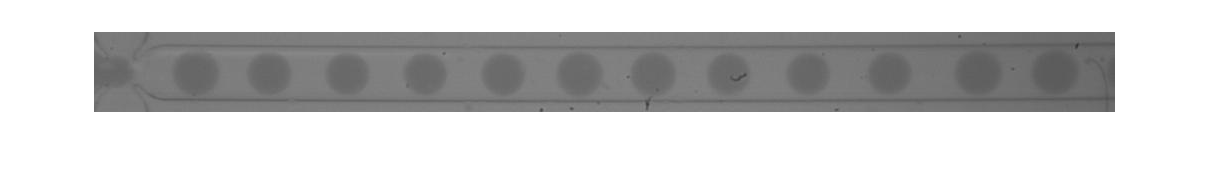

% Load images
I = imread('19.jpg');   %<-------- user-defined input!!

% check images loaded correctly
figure; imshow(I);  

## 4) Image processing

- Background subtraction

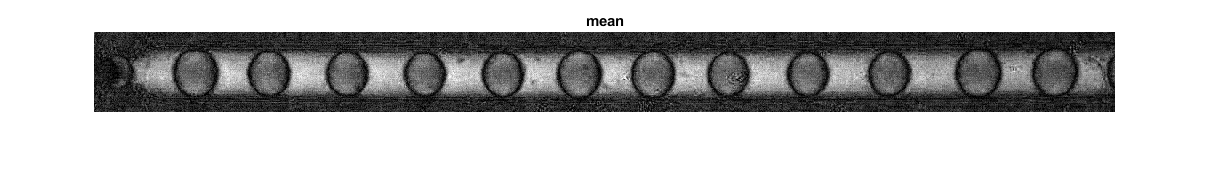

% From Mean background generation
subMean = rescale(abs(double(I) - double(mean_pix))); 
% From Median background generation
subMed = rescale(abs(double(I) - double(med_pix))); %imshow(subMed); 
% From Mode background generation
subMax = rescale(abs(double(I) - double(max_pix))); %imshow(subMax)
% imshowpair(subMed, subMax, 'montage');

% From complex background generation method 
subCom = rescale(abs(double(I) - double(R)));

figure; imshow(subMean); title('mean')

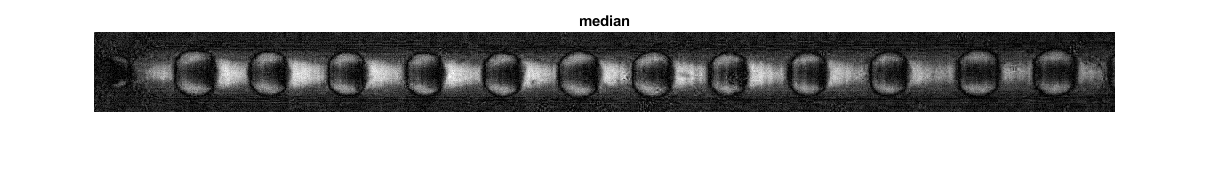

figure; imshow(subMed); title('median')

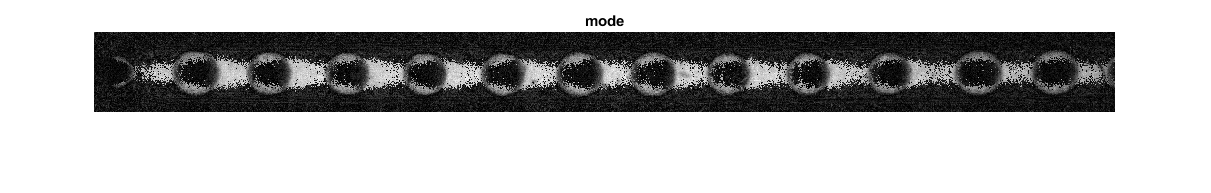


figure; imshow(subMax); title('mode')

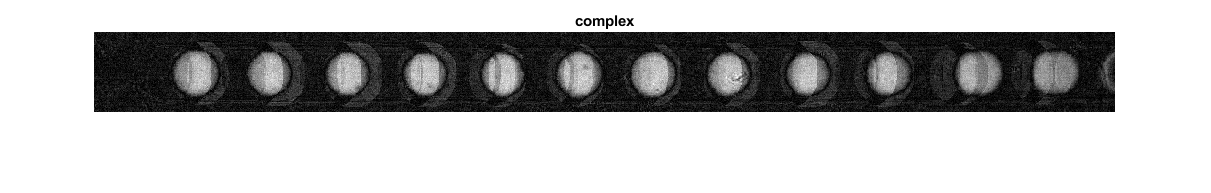

figure; imshow(subCom); title('complex')

- Binarise image

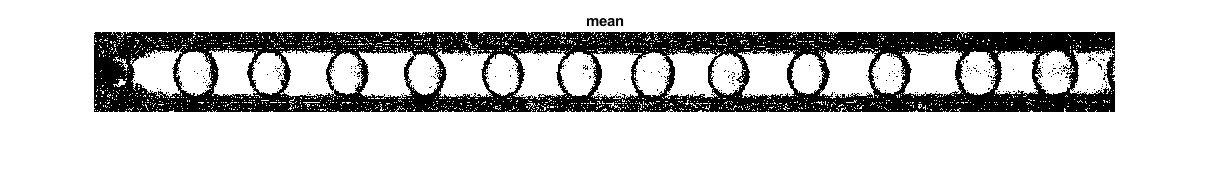

treshold = 0.25; %<-------- user-defined input!!
bin1= imbinarize(subMean, treshold); 
bin2= imbinarize(subMed, treshold);
bin3= imbinarize(subMax, treshold); 
bin4= imbinarize(subCom, treshold); 
% imshowpair(bin1, bin2, 'montage');
figure; imshow(bin1); title('mean')

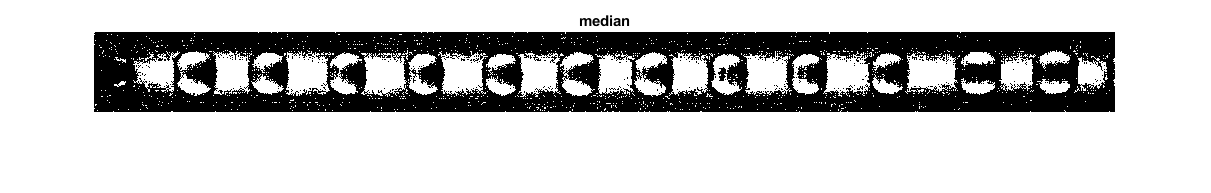

figure; imshow(bin2); title('median')

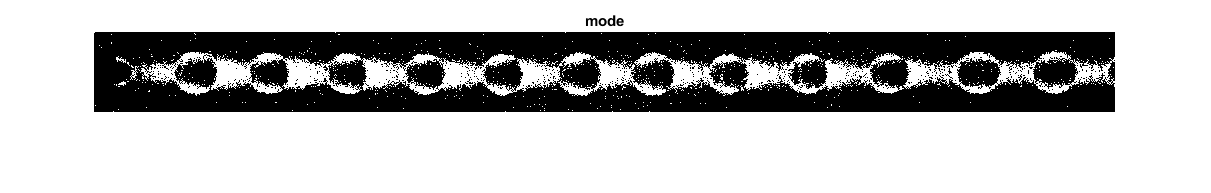


figure; imshow(bin3); title('mode')

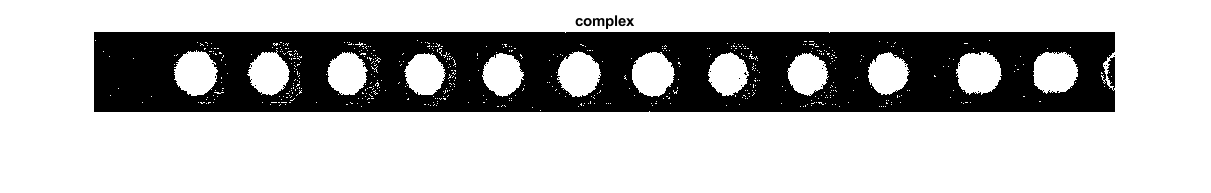

figure; imshow(bin4); title('complex')

- Morphological fill

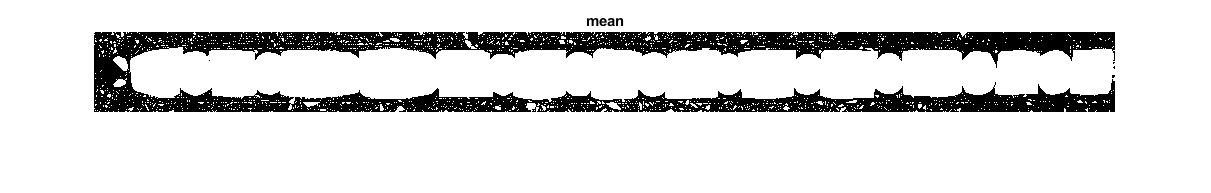

fill1 = bwconvhull(bin1, 'objects'); 
fill2 = bwconvhull(bin2, 'objects'); 
fill3 = bwconvhull(bin3, 'objects'); 
fill4 = bwconvhull(bin4, 'objects'); 
% imshowpair(fill1, fill2, 'montage');
figure; imshow(fill1); title('mean')

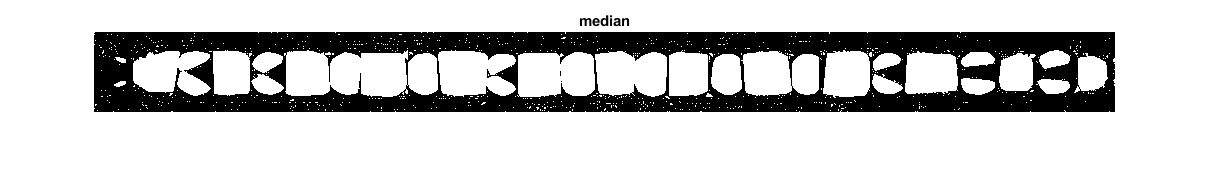

figure; imshow(fill2); title('median')

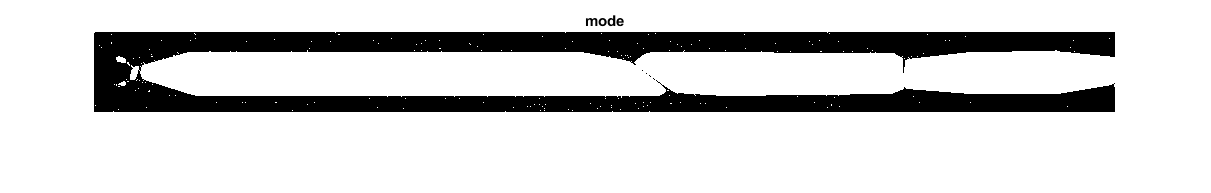

figure; imshow(fill3); title('mode')

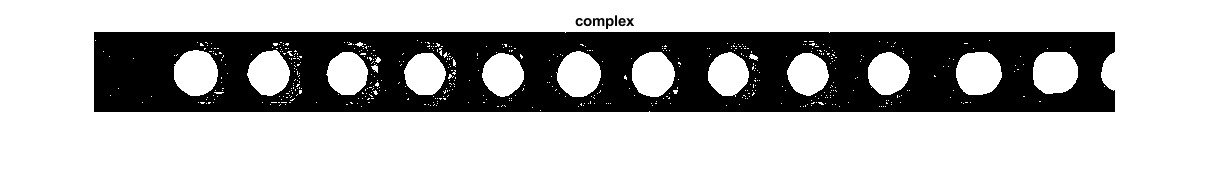

figure; imshow(fill4); title('complex')



%detect ROI
ROI1 = regionprops('table',fill1) 

ROI1 = 1693×3 table
    Area        Centroid                BoundingBox        
    ____    ________________    ___________________________

     1           1         1    0.5     0.5       1       1
     1           1         3    0.5     2.5       1       1
     1           1        13    0.5    12.5       1       1
     1           1        77    0.5    76.5       1       1
     1           2         7    1.5     6.5       1       1
     3      2.3333    9.6667    1.5     8.5       2       2
     1           2        42    1.5    41.5       1       1
     1           2        47    1.5    46.5       1       1
     1           2        69    1.5    68.5       1       1
     3      2.3333    73.333    1.5    72.5       2       2
     1           2        79    1.5    78.5       1       1
     3      3.6667        59    2.5    57.5       2       3
     2           3      64.5    2.5  

ROI2 = regionprops('table',fill2) 

ROI2 = 802×3 table
    Area        Centroid                BoundingBox         
    ____    ________________    ____________________________

     1           1         1     0.5     0.5       1       1
     1           1         3     0.5     2.5       1       1
     1           1        13     0.5    12.5       1       1
     1           1        77     0.5    76.5       1       1
     1           2         9     1.5     8.5       1       1
     3      2.3333    73.333     1.5    72.5       2       2
     1           4        79     3.5    78.5       1       1
     1           6        14     5.5    13.5       1       1
     1           6        24     5.5    23.5       1       1
     2         7.5        16     6.5    15.5       2       1
     1           8        39     7.5    38.5       1       1
     1           8        59     7.5    58.5       1       1
     2         8.5      

ROI3 = regionprops('table',fill3) 

ROI3 = 177×3 table
    Area        Centroid                BoundingBox         
    ____    ________________    ____________________________

      1          1         1     0.5     0.5       1       1
      1          2        74     1.5    73.5       1       1
      1          6        14     5.5    13.5       1       1
      1          8        16     7.5    15.5       1       1
      1         18         3    17.5     2.5       1       1
      2         18      11.5    17.5    10.5       1       2
      1         20        80    19.5    79.5       1       1
      1         21        53    20.5    52.5       1       1
     51     27.549    28.255    22.5    24.5      10       7
      2         23      53.5    22.5    52.5       1       2
     26     29.231    52.269    24.5    49.5       8       5
      2       25.5        55    24.5    54.5       2       1
      1         25      

ROI4 = regionprops('table',fill4) 

ROI4 = 519×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

       1         2         9      1.5      8.5        1        1
       1        10        20      9.5     19.5        1        1
       1        16        25     15.5     24.5        1        1
       1        17        64     16.5     63.5        1        1
       1        25        57     24.5     56.5        1        1
       1        40        27     39.5     26.5        1        1
       1        49        71     48.5     70.5        1        1
       1        58        65     57.5     64.5        1        1
       1        81        24     80.5     23.5        1        1
    1596    102.47    41.551     80.5     18.5       44       46
       2      83.5      23.5     82.5     22.5        2        2
       1       104        11    1

- Noise objects removal

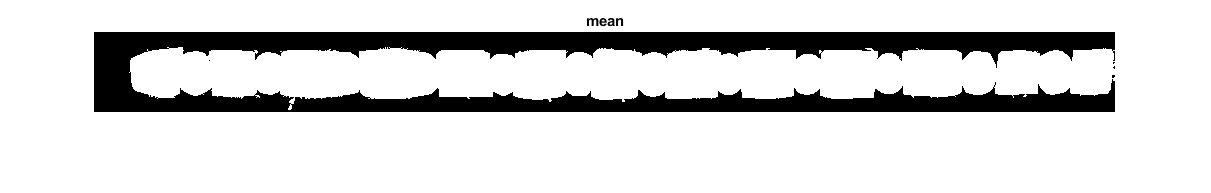

cfill1 = bwareaopen(fill1,1000);
cfill2 = bwareaopen(fill2,1000);
cfill3 = bwareaopen(fill3,1000);
cfill4 = bwareaopen(fill4,1000);

% figure; imshowpair(cfill1, cfill2, 'montage')
figure; imshow(cfill1); title('mean')

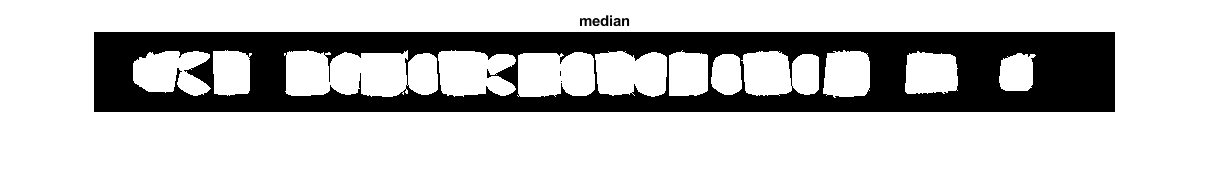

figure; imshow(cfill2); title('median')

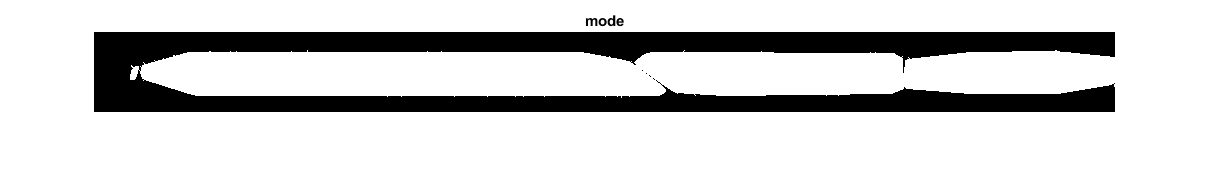

figure; imshow(cfill3); title('mode')

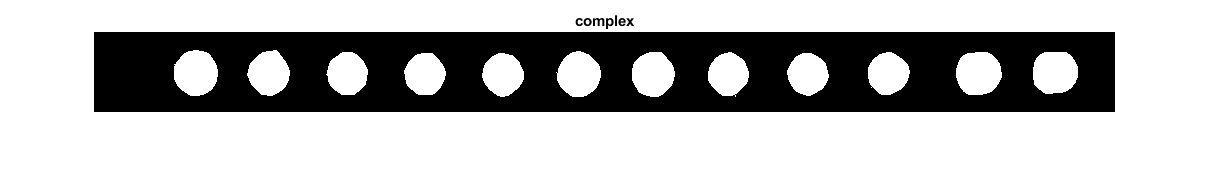

figure; imshow(cfill4); title('complex')


% detect ROI
cROI1 = regionprops('table',cfill1) %ROI1 = struct2table(ROI1)

cROI1 = 1×3 table
    Area         Centroid                BoundingBox         
    _____    ________________    ____________________________

    43796    524.07    42.189    35.5    15.5     986      63



cROI2 = regionprops('table', cfill2) %ROI2 = struct2table(ROI2)

cROI2 = 12×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    2515    76.576    40.819     39.5     19.5       78       45
    1564    137.91    41.343    119.5     18.5       39       46
    6037    266.63    42.393    190.5     18.5      154       47
    2883    380.14    41.774    344.5     18.5       78       47
    3155    462.04     43.06    423.5     20.5       78       45
    2817     537.9    42.198    501.5     19.5       72       46
    1641    594.66    42.625    575.5     18.5       39       46
    1068    633.44    43.025    617.5     22.5       31       41
    2923    686.73    42.369    647.5     19.5       78       45
    1966    753.68     42.76    729.5     18.5       47       48
    1996    837.49    41.932    811.5     19.5       53       43
    1144     923.4    41.434    9

cROI3 = regionprops('table', cfill3) %ROI3 = struct2table(ROI3)

cROI3 = 1×3 table
    Area        Centroid                BoundingBox         
    _____    _______________    ____________________________

    40117    528.7    42.237    36.5    18.5     985      48


cROI4 = regionprops('table',cfill4) %ROI4 = struct2table(ROI4)

cROI4 = 12×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    1596    102.47    41.551     80.5     18.5       44       46
    1443     175.5    41.783    153.5     18.5       43       46
    1375    253.92     42.22    232.5     20.5       42       43
    1360    331.49    42.725    310.5     21.5       42       42
    1372    409.53    43.101    388.5     21.5       42       44
    1541    485.41     43.01    462.5     19.5       45       46
    1519    559.57    42.862    538.5     20.5       43       45
    1358    634.84    42.833    614.5     20.5       41       45
    1345    714.41    42.683    693.5     21.5       42       43
    1368    794.75    42.112    774.5     20.5       42       43
    1613    885.02    41.843    862.5     20.5       46       43
    1592    961.51    40.976    9

- Remove drops outside of main flow channel

delCriteria = 100; % remove drop if centroid position < delCritera  <-------- user-defined input!!

cROI1(cROI1.Centroid(:,1) < delCriteria, :) = []

cROI1 = 1×3 table
    Area         Centroid                BoundingBox         
    _____    ________________    ____________________________

    57018    500.77     41.73    19.5     0.5    1002      80


cROI2(cROI2.Centroid(:,1) < delCriteria, :) = []

cROI2 = 4×3 table
    Area         Centroid                  BoundingBox           
    _____    ________________    ________________________________

    20205    272.47    42.116     38.5     15.5      463       56
    16094    681.65     42.56    501.5     16.5      365       52
     2035    933.48    37.725    904.5     18.5       74       44
     1283     996.7    42.051    978.5     20.5       36       42


cROI3(cROI3.Centroid(:,1) < delCriteria, :) = []

cROI3 = 1×3 table
    Area         Centroid                BoundingBox         
    _____    ________________    ____________________________

    45817    528.76    42.077    19.5    15.5    1002      56



cROI4(cROI4.Centroid(:,1) < delCriteria, :) = []

cROI4 = 12×3 table
    Area        Centroid                  BoundingBox           
    ____    ________________    ________________________________

    1951    104.71    38.459     79.5     10.5       52       55
    2831    184.15     42.78    153.5      9.5       58       65
    2600    262.87    41.021    232.5      9.5       56       60
    2411    338.57    43.545    310.5     10.5       53       66
    1489    409.34    43.423    387.5     20.5       43       50
    1618    485.48    43.047    462.5     19.5       45       48
    2007    562.37     44.17    537.5     12.5       50       62
    1442    634.96    43.094    614.5     20.5       42       45
    2059    718.12    40.149    693.5      9.5       51       66
    1483     794.9    42.492    773.5     20.5       44       44
    1735    885.07    41.771    861.5     19.5       47       45
    1736    961.45     40.98    9

## 5) Plot results

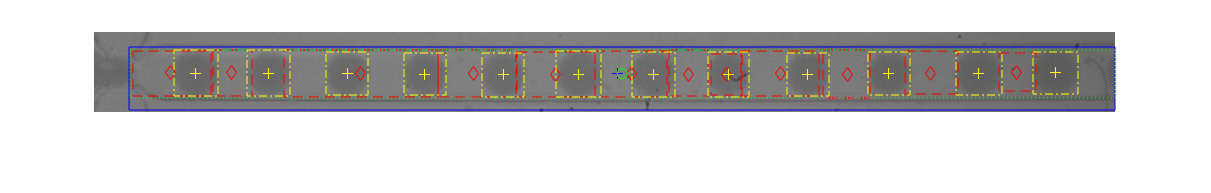

figure; imshow(I);
hold on

% from ROI1 data
plot(cROI1.Centroid(:,1), cROI1.Centroid(:,2), 'b+')

for i=1:height(cROI1)
    rectangle('Position',cROI1.BoundingBox(i,:),'EdgeColor','b')
end

% from ROI2 data
plot(cROI2.Centroid(:,1), cROI2.Centroid(:,2), 'rd')

for i=1:height(cROI2)
    rectangle('Position',cROI2.BoundingBox(i,:),'EdgeColor','r','LineStyle', '--')
end

% from ROI3 data
plot(cROI3.Centroid(:,1), cROI3.Centroid(:,2), 'go')

for i=1:height(cROI3)
    rectangle('Position',cROI3.BoundingBox(i,:),'EdgeColor','g','LineStyle', ':')
end

% from ROI4 data
plot(cROI4.Centroid(:,1), cROI4.Centroid(:,2), "y+")

for i=1:height(cROI4)
    rectangle('Position',cROI4.BoundingBox(i,:),'EdgeColor','y','LineStyle', '-.')
end

## 6) Crop and show individual drops 

 
roiTable = cROI4.BoundingBox; 
cropSize = [128 128];

for i = 1: height(roiTable)
    dim = max([roiTable(i,3:4)]); % this will be the width/ height of square cropped area
    % x-coord of centroid of cropping region
    cx = roiTable(i,1) + roiTable(i,3)/2; 
    % y-coord of centroid of cropping region
    cy = roiTable(i,2) + roiTable(i,4)/2; 
    
    % coordinates of bottom-left vertex of intended crop region 
    xmin = cx - dim/2 - 0.15*dim;
    ymin = cy - dim/2 - 0.15*dim; 
    
    % crop region defined as [x-coord of bottom left point, y-coord of
    % bottom left point, width, height]
    Img = imcrop(I, [xmin, ymin, 1.3*dim, 1.3*dim]);
    
    % resize cropped image
    Img = imresize(Img, cropSize);
    
    %show image
    figure; imshow(Img)
end 

% % test= bwmorph(fill1,'remove');
% se = strel('disk', round(0.15*min(cROI1.BoundingBox(:,3))));
% test = imdilate(cfill1,se);
% figure; imshow(test)
% figure; imshowpair(cfill1,test)